# Implement

**Tractor implement defined by tool-soil interaction parameters, user-defined force data.**

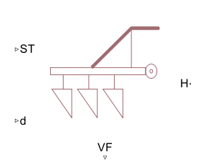

Copyright 2024 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:web('TractorModelOverview.html')).

## Description

The Implement block represents an implement or tool that connects to and exerts force on the drawbar of a tractor. The draft force is the horizontal component of the force exerted by the implement. The draft force resists the tractor forward motion. The vertical component of the force exerted by the implement acts on the rear wheels. The vertical force leads to sinkage of the rear wheels when the tractor moves forward.

### Model

The below figure shows a narrow tillage implement connected to a drawbar of tractor.

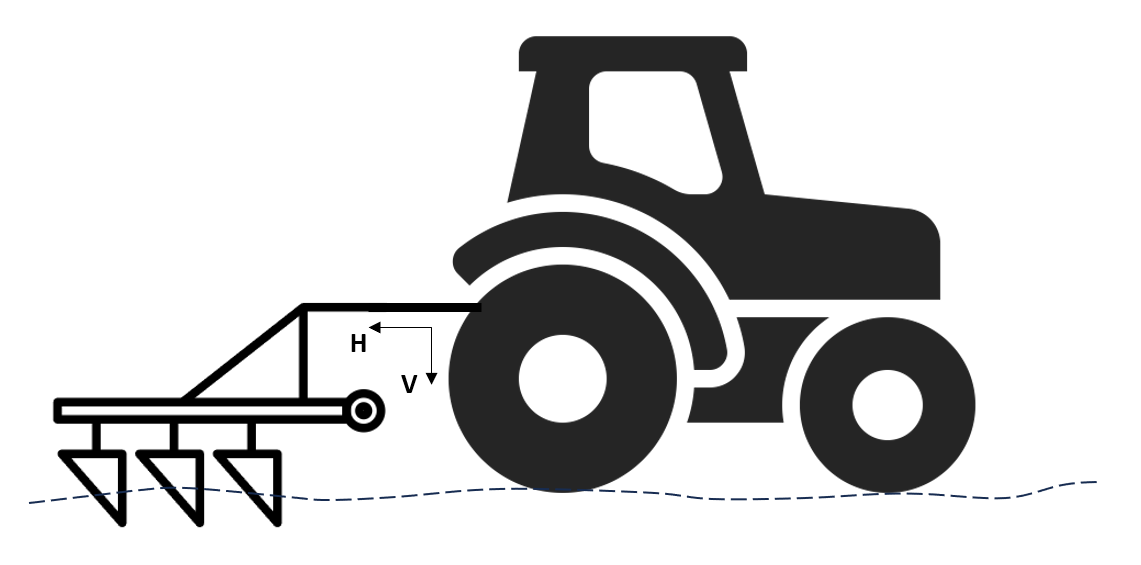

The below figure shows the implement cutting and dragging the failed soil wedge.

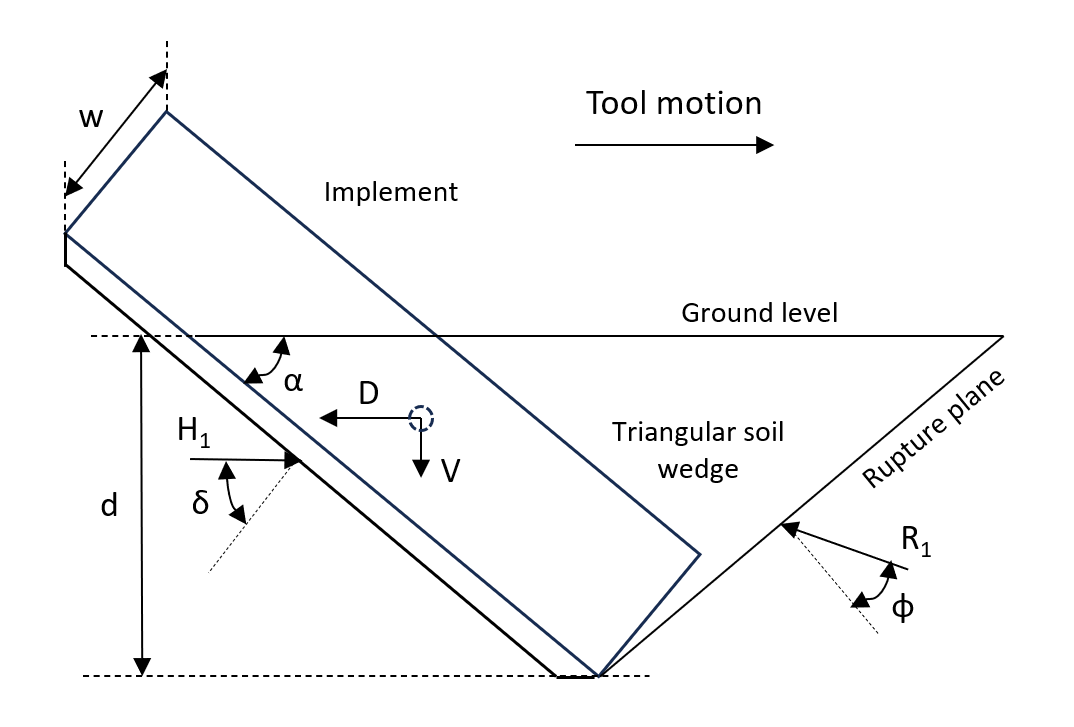

Where:

- $d$ is the tillage depth.

- $w$ is the implement width.

- $R_1$is the reaction force at the rupture plane.

- $H_1$is the soil resisting force or horizontal force on soil.

- $\alpha$ is the tool rake angle.

- $\delta \;$is the soil-metal friction angle.

- $\phi$ is the soil internal friction angle.

- $D$ is the draft force or horizontal component of force exerted by implement.

- $V$ is the vertical component of force exerted by implement.

### Draft (Horizontal) Force and Vertical Force Computation

#### Draft Force Prediction Based on ASABE 497.5 Standard

Draft force data are reported as the force required in the horizontal direction of travel. The data includes functional draft force, such as soil and crop resistance, and draft force required to overcome rolling resistance of the implement. For manure injection, the motion resistance of spreader transport wheels must be added to get total implement draft force. 

The draft force required to pull most seeding implements and minor tillage tools operated at shallow depths is primarily a function of the width of the implement and the speed at which it is pulled. For tillage tools operated at deeper depths, the draft force also depends on soil texture, depth, and tool geometry. Typical draft force requirements can be calculated as


$$D=F_{i\;} \left\lbrack A+B\left(S\right)+C{\left(S\right)}^2 \right\rbrack \textrm{WT}$$


where:

$D$ is implement draft force, N (lbf);

$F$ is a dimensionless soil texture adjustment parameter (table1);

$i$ = 1 for fine, 2 for medium and 3 for coarse textured soils;

$A$, $B$ and $C$ are machine-specific parameters (table1);

$S$ is field speed, km/h (mile/h).

$W$ is machine width, m (ft) or number of rows or tools (table1);

$T$ is tillage depth, cm (in.) for major tools, 1 (dimensionless) for minor tillage tools and seeding implements.

Table 1 - Draft force parameters and an expected range in draft force estimated by model parameters for tillage implements (derived from ASABE 497.5 standard) [1]

Table 1 summarizes typical average draft force parameters for seeding and tilling machines. Each parameter is a function of tillage tool design. The constant parameter, A, is a function of soil strength. The coefficient of speed parameters, B or C, are related to soil bulk density. Soil is categorized as fine, medium, or coarse. Fine-textured soil has high clay content, medium textured are loamy, and coarse textured are sandy. The table lists typical values of all parameters along with an expected range or variation due to differences in machine design, machine adjustment, machine age, and site-specific conditions, including soil moisture and residue cover.

#### Compute Draft Force

You can quickly estimate the draft force of an implement based on the values of the parameters you set.

typeImplement   = "Chisel plow - 5 cm straight point"; % Type of implement
widthImplement  = 5; % Width of implement (tools or m)
depthTillage    = 10; % Depth of tillage (cm)
textureSoil     = "Coarse"; % Texture of soil (Fine-high clay content, medium-loamy soil, coarse-sandy soil)
velocityTractor = 4; % Velocity of tractor (km/h)
if (typeImplement == "Subsoiler - narrow point")
    A = 226;
    B = 0;
    C = 1.8;
elseif (typeImplement == "Moldboard plow")
    A = 652;
    B = 0;
    C = 5.1;
elseif (typeImplement == "Chisel plow - 5 cm straight point")
    A = 91;
    B = 5.4;
    C = 0;
elseif (typeImplement == "Sweep plow for primary tillage")
    A = 390;
    B = 19;
    C = 0;
elseif (typeImplement == "Field cultivator for primary tillage")
    A = 46;
    B = 2.8;
    C = 0;
end

if textureSoil == "Fine", Fi = 1; 
elseif (typeImplement == "Subsoiler - narrow point") || (typeImplement == "Moldboard plow")
    if textureSoil == "Medium", Fi = 0.7; else, Fi = 0.45; end
else
    if textureSoil == "Medium", Fi = 0.85; else, Fi = 0.65; end
end
draftForce      = Fi*(A + B*velocityTractor + C*velocityTractor^2)*widthImplement*depthTillage; % Draft force (N)
fprintf('Draft force is %.3f N.\n',draftForce);

Draft force is 3659.500 N.


#### **Compute Vertical Force**

You can compute the vertical component of the force exerted by implement on tractor based on the below formulation [2]. Vertical force in upward direction is considered positive.


$$D=P\;\sin \left(\alpha +\delta \right)+C_a \;\textrm{dw}\;\cot \;\alpha$$



$$V=-\;P\;\cos \left(\alpha +\delta \right)-C_a \;\textrm{dw}$$


Since, the block does not include adhesion components of soil reaction, the above equations can be reformulated as below.


$$D=P\;\sin \left(\alpha +\delta \right)$$



$$V=-\;P\;\cos \left(\alpha +\delta \right)$$



$$V=-\;D\frac{\cos \left(\alpha +\delta \right)}{\sin \left(\alpha +\delta \right)}$$


where:

- $P$ is total force exerted by implement

- $D$ is implement draft force or horizontal component of total force

- $V$ is implement vertical force or vertical component of total force

- $\alpha$ is implement rake angle

- $\delta$ is soil-metal friction angle

- $C_a$ is soil adhesion coefficient

- $d$ is tillage depth

- $w$ is implement width

#### **Limitations and Assumptions**

- Soil texture is a stable input to the implement. Soil texture does not change for a specific agricultural farm land and during the tillage operation. It is not influenced by the compaction of tractor wheels.

- Moisture content in the soil is assumed to be low. The block does not include adhesion components of soil reaction.

- The draft force predicted by this method has an expected range of variation due to differences in machine design, machine adjustment, machine age, and site-specific conditions including soil moisture and residue cover.

- This block neglects the effects of inertia forces.

- This block applies well to tractors moving at low speeds and operating at shallow depths.

#### Specify Vectors for Draft Force, Vertical Force and Velocity

To calculate draft force and vertical force according to the user-provided tabulated data of draft force, vertical force and velocity:

`draft_force = tablelookup(velocity_vector,draft_vector,velocity,interpolation=linear,extrapolation=nearest);`

`vertical_force = tablelookup(velocity_vector,VF_vector,velocity,interpolation=linear,extrapolation=nearest);`

where:

`velocity` is velocity of conserving port of block associated with the horizontal motion of the implement

`velocity_vector `is the user-provided velocity vector.

`draft_vector` is the user-provided draft force vector.

`VF_vector` is the user-provided vertical force vector.

## Ports

### Input

#### S - Soil texture

Physical signal input port carrying information of soil texture adjustment parameter. To enable this port, set **Draft (horizontal) force and vertical force computation **to `Draft force prediction based on ASABE 497.5 standard`.

#### D - Depth of tillage

Physical signal input port carrying information of depth of the tillage.

### Output

#### VF - Vertical force

Physical signal output port carrying information of the implement vertical force.

### Conserving

#### H - Horizontal motion

Conserving port associated with the horizontal motion of the implement. Connect the vehicle to this port.

## Parameters

### Main

#### Draft (horizontal) force and vertical force computation - Method of draft force and vertical force computation

Method 1: When **Draft (horizontal) force and vertical force computation **is set to `Draft force prediction based on ASABE 497.5 standard`, the block computes the draft force and vertical force based on the draft force parameters as specified in tabular format derived from ASABE 497.5 standard.

Method 2: When **Draft (horizontal) force and vertical force computation **is set to `Specify vectors for draft force, vertical force and velocity`, users can provide vectors for draft force, vertical force and velocity to calculate draft force and vertical force.

#### Implement type - Type of implement

Subsoiler - narrow point: This is a narrow implement used for tillage operation. 

Moldboard plow: This is a wide implement used for tillage operation.

Chisel plow - 5 cm straight point: This is a narrow implement used for tillage operation.

Sweep plow for primary tillage: This is a wide implement used for primary tillage operation.

Field cultivator for primary tillage: This is a narrow implement used for primary tillage operation.

#### Implement width - Width of implement

Width for narrow implement: If the **Implement type** is set to `Subsoiler - narrow point` or `Chisel plow - 5 cm straight point` or `Field cultivator for primary tillage`, specify width of implement as a dimensionless parameter, **Number of tools**.

Width for wide implements: If the **Implement type** is set to `Moldboard plow` or `Sweep plow for primary tillage`, specify implement width as a dimensional (length) parameter **Implement width**.

#### Implement rake angle - Rake angle of implement

Angle of implement cutting face with the horizontal.

#### Draft force vector - Vector for draft force

Vector of draft force for the `Specify vectors for draft force, vertical force and velocity `method of **Draft (horizontal) force and vertical force computation**. This vector must have the same number of elements as the velocity vector.

#### Vertical force vector - Vector for vertical force

Vector of vertical force for the `Specify vectors for draft force, vertical force and velocity `method of **Draft (horizontal) force and vertical force computation**. This vector must have the same number of elements as the velocity vector.

#### Velocity vector - Vector for tractor velocity

Vector of velocity for the `Specify vectors for draft force, vertical force and velocity `method of **Draft (horizontal) force and vertical force computation**.

### Advanced

#### Velocity threshold

Threshold velocity the block uses to transition the draft force and vertical force when tractor changes direction from forward motion to reverse motion or vice versa. The parameter ensures that the force remains continuous during velocity direction changes, which increases the numerical stability of the simulation. The parameter must be greater than zero.

#### Minimum valid depth

Minimum valid implement depth. The parameter must be greater than zero. 

## References

[1] ASAE 497.5 Feb 2006 Agricultural Machinery Management Data

[2] E.McKyes, "Soil Cutting and Tillage" (1985)